close all
clear 
clc

% part 1 - find the state space and the lamdot 

% define variables
R = 0.6; % [hr/m^2]
A = 1; % [m^2]
matA1 = [[-5/3 5/3 0];[5/3 -10/3 5/3];[0 5/3 -10/3]]

matA1 =    -1.6667    1.6667         0
    1.6667   -3.3333    1.6667
         0    1.6667   -3.3333


matB1 = [[0 1]; [1 0]; [0 0]]

matB1 =      0     1
     1     0
     0     0


matB1u = [0; 1; 0];
matC1 =eye(3);
[eigV1 ,eigD1 ] = eig(matA1) % Eigenvalues and eigenvectors open loop

eigV1 =     0.3280    0.5910    0.7370
   -0.7370   -0.3280    0.5910
    0.5910   -0.7370    0.3280


eigD1 =    -5.4116         0         0
         0   -2.5916         0
         0         0   -0.3301


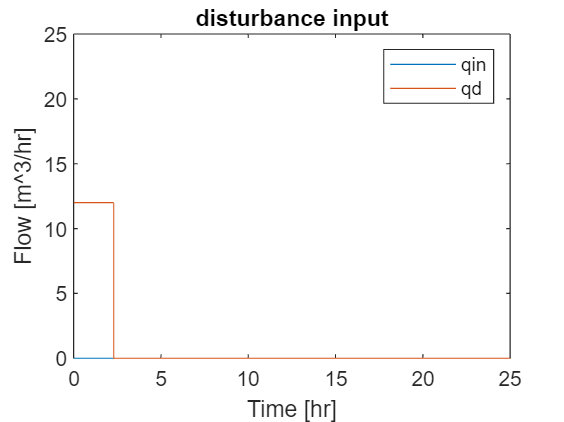

% part 2 

% qd = 12 [m^3/hr] for 2.3 [hr]
out2 = sim('sim_part2.slx');
plot(out2.u2)
title('disturbance input')
legend('qin','qd')
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')
ylim([0 25])

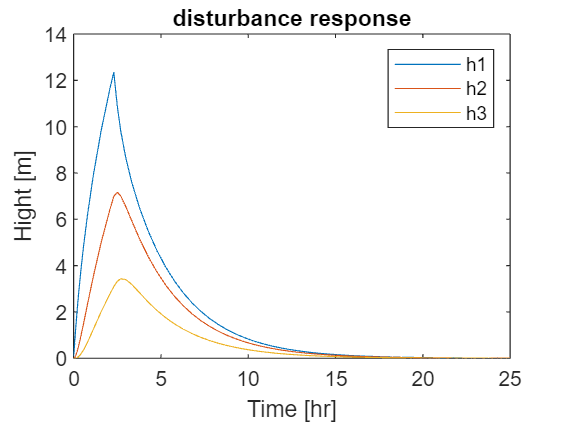

plot(out2.y2)
xlim([0,25])
title('disturbance response')
legend('h1','h2','h3')
xlabel('Time [hr]')
ylabel('Hight [m]')

% Limitations: |qin|<=13.4[m^3/hr], hi(t) > -1.6[m]

% part 3

Mc1 = ctrb(matA1,matB1u) % Controllability matrix

Mc1 =          0    1.6667   -8.3333
    1.0000   -3.3333   16.6667
         0    1.6667  -11.1111


%det_Mc1 = det(Mc1) % det != 0 -> The system is controllable
k= rank(Mc1) %another way to check if the system is controllable

k = 3

Pmin = -3.215; 
Pmax = -0.746;
fprintf('Poles range: -0.746 > P > -3.215');

Poles range: -0.746 > P > -3.215

F1_min = acker(matA1,matB1u,[Pmin Pmin Pmin])

F1_min =     3.0029    1.3117    1.6673


F1_max = acker(matA1,matB1u,[Pmax Pmax Pmax])

F1_max =     1.3857   -6.0953    7.9020


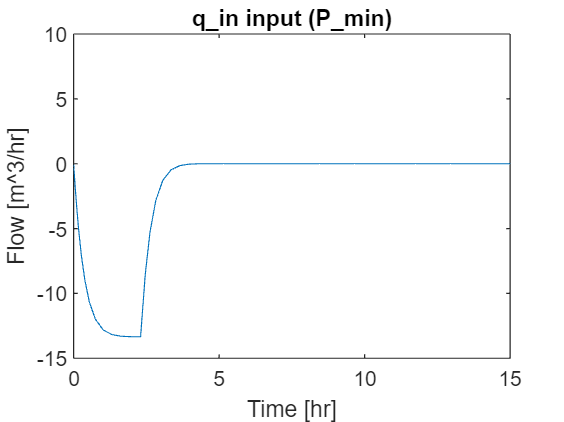

out3 = sim('sim_part3.slx');
plot(out3.q_in3)
title('q_in input (P_min)')
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')
ylim([-15 10])

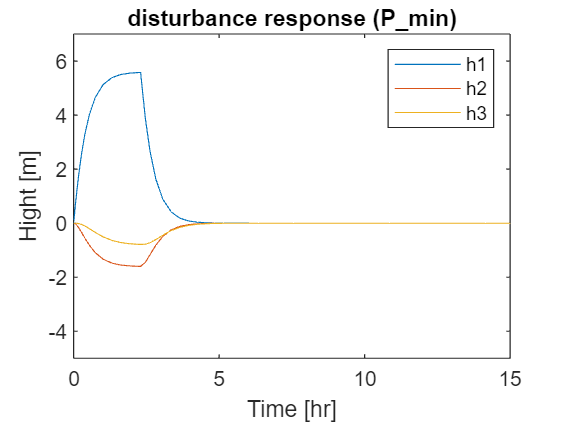

plot(out3.y3)
title('disturbance response (P_min)')
legend('h1','h2','h3')
xlabel('Time [hr]')
ylabel('Hight [m]')
ylim([-5 7])


F1_max

F1_max =     1.3857   -6.0953    7.9020


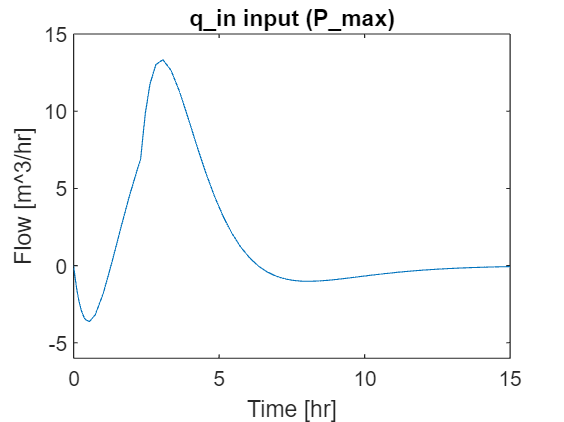

plot(out3.q_in3m)
title('q_in input (P_max)')
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')
ylim([-6 15])

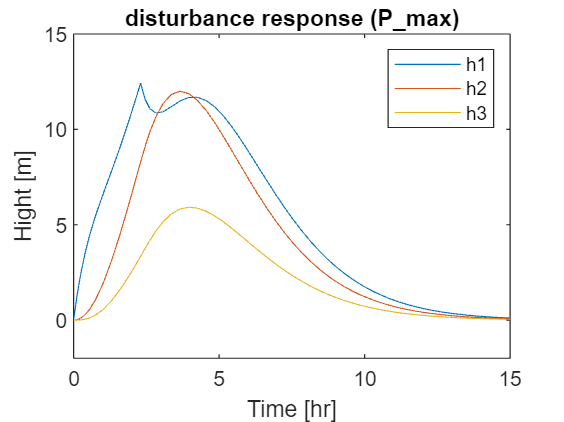

plot(out3.y3m)
title('disturbance response (P_max)')
legend('h1','h2','h3')
xlabel('Time [hr]')
ylabel('Hight [m]')
ylim([-2 15])

% Limitations: |qin|<=13.4[m^3/hr], hi(t) > -1.6[m]

% part 4


% Riccati - LQR
rho_min = 0.005 

rho_min = 0.0050

rho_max = 1000; % inf
[F4,matP4,eigD4] = lqr(matA1,matB1u,eye(3),rho_min);
[F4_max,matP4_max,eigD4_max] = lqr(matA1,matB1u,eye(3),rho_max);
F4

F4 =     6.3067   12.2911    3.5969


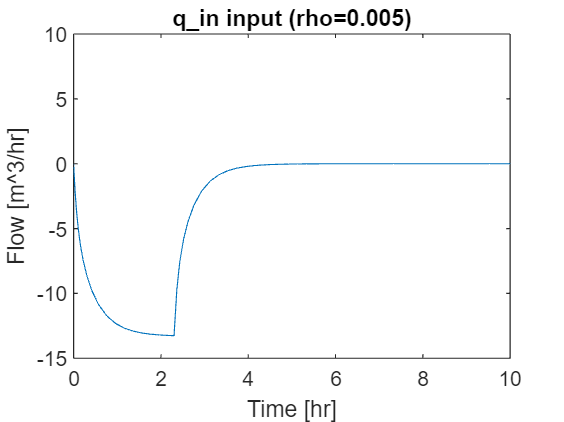


out4 = sim('sim_part4.slx');
plot(out4.q_in4)
title('q_in input (rho=0.005)')
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')
ylim([-15 10])

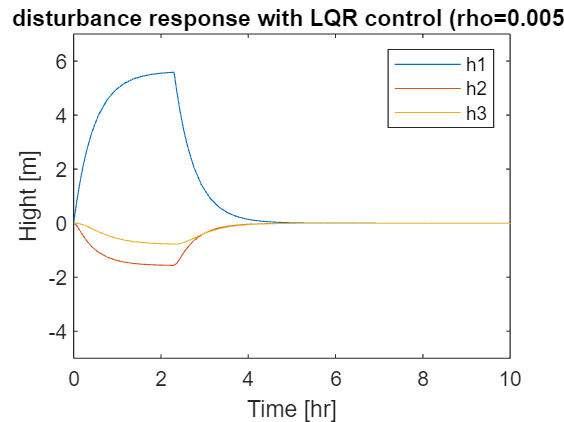

plot(out4.y4)
title('disturbance response with LQR control (rho=0.005)')
legend('h1','h2','h3')
xlabel('Time [hr]')
ylabel('Hight [m]')
ylim([-5 7])


rho_max

rho_max = 1000

F4_max

F4_max = 1.0e-03 *

    0.5995    0.5996    0.2998


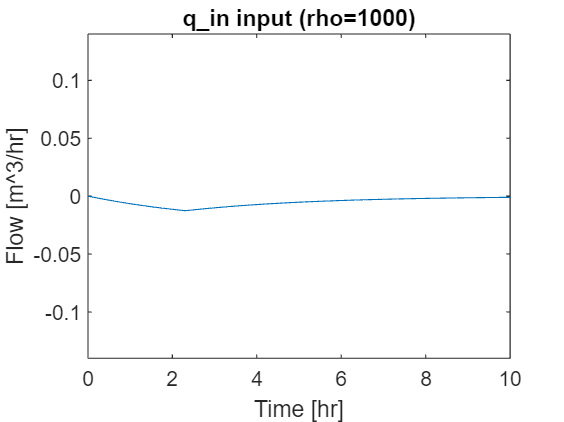

plot(out4.q_in4m)
title('q_in input (rho=1000)')
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')
ylim([-0.14 0.14])

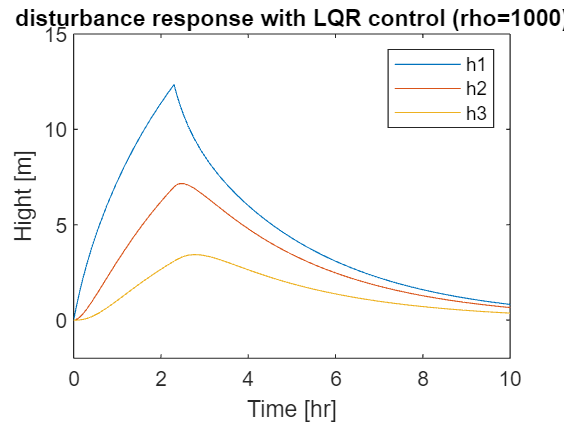

plot(out4.y4m)
title('disturbance response with LQR control (rho=1000)')
legend('h1','h2','h3')
xlabel('Time [hr]')
ylabel('Hight [m]')
ylim([-2 15])

% part 5


zeta = 0.8;
R = 4.1; % R5 = Radius and equal to Wn of the complex poles  
P5 = [-R -R (-zeta*R+1i*(sqrt(1-zeta^2))) (-zeta*R-1i*(sqrt(1-zeta^2)))]

P5 =   -4.1000 + 0.0000i  -4.1000 + 0.0000i  -3.2800 + 0.6000i  -3.2800 - 0.6000i



matC5 = [0,0,5/3]

matC5 =          0         0    1.6667


matA5 =[[matA1,[0;0;0]];[-matC5,0]]

matA5 =    -1.6667    1.6667         0         0
    1.6667   -3.3333    1.6667         0
         0    1.6667   -3.3333         0
         0         0   -1.6667         0


matB5u = [matB1u;0]

matB5u =      0
     1
     0
     0


Mc5 = ctrb(matA5,matB5u) % Controllability matrix

Mc5 =          0    1.6667   -8.3333   41.6667
    1.0000   -3.3333   16.6667  -87.9630
         0    1.6667  -11.1111   64.8148
         0         0   -2.7778   18.5185


%det_Mc5 = det(Mc5) 
k5= rank(Mc5)

k5 = 4

F5t = acker(matA5,matB5u,P5)

F5t =    -2.1227    6.4267   21.8749  -40.3705


F5 = [F5t(1),F5t(2),F5t(3)]

F5 =    -2.1227    6.4267   21.8749


beita5 = -F5t(4)

beita5 = 40.3705

fprintf('R = 4.1');

R = 4.1

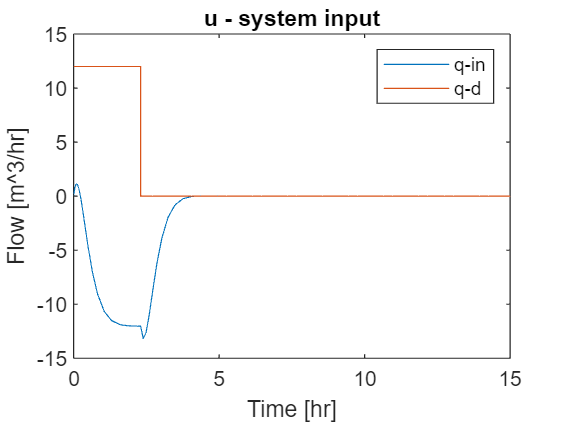


out5 = sim('sim_part5.slx');
plot(out5.u5)
title('u - system input')
legend('q-in','q-d')
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')

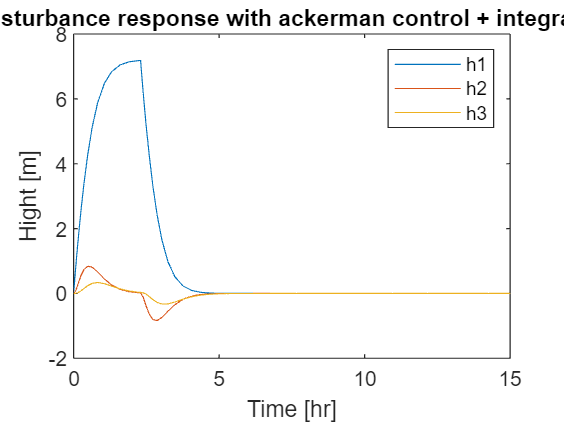

% ylim([-10 10])
plot(out5.x5)
title('disturbance response with ackerman control + integrator')
legend('h1','h2','h3')
xlabel('Time [hr]')
ylabel('Hight [m]')
ylim([-2 8])

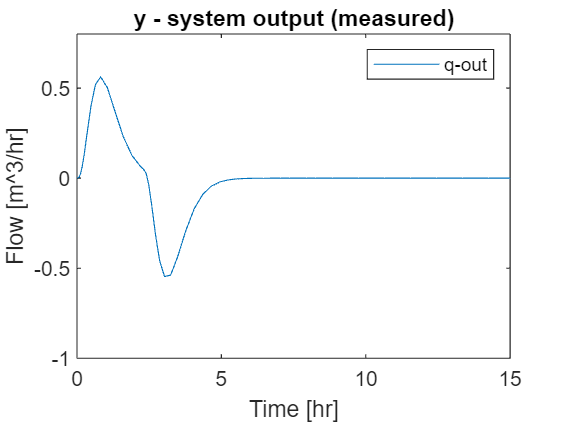

plot(out5.y5)
title('y - system output (measured)')
legend('q-out')
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')
ylim([-1 0.8])

% part 6



matC6 = [0 0 5/3];
Mo6 = obsv(matA1,matC6) % Observability matrix

Mo6 =          0         0    1.6667
         0    2.7778   -5.5556
    4.6296  -18.5185   23.1481


rank_Mo6= rank(Mo6) %  way to check if the system is observable

rank_Mo6 = 3

V6 = 0; %Accurate measurement
V7 = 0.15;%
P6_1 = [-3 -4.5+1i*2 -4.5-1i*2]

P6_1 =   -3.0000 + 0.0000i  -4.5000 + 2.0000i  -4.5000 - 2.0000i


P6_2 = [-18 -26+1i*12 -26-1i*12]

P6_2 =  -18.0000 + 0.0000i -26.0000 +12.0000i -26.0000 -12.0000i


K61 = acker(matA1',matC6',P6_1)

K61 =     6.6640    5.8500    2.2000


K62 = acker(matA1',matC6',P6_2)

K62 = 1.0e+03 *

    2.6350    0.5152    0.0370


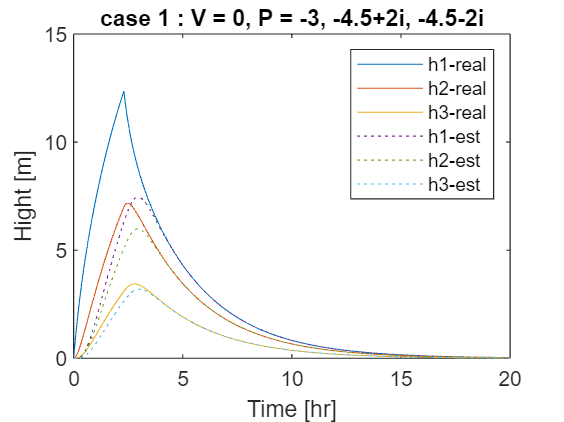

% same for check 
% k7 = (matA1-P6_1(1)*eye(3))*(matA1-P6_1(2)*eye(3))*(matA1-P6_1(3)*eye(3))*(Mo6^(-1))*[0;0;1]

% part 7

out6 = sim('sim_part6.slx');

plot(out6.x61)
hold on
plot(out6.xe61,':')
title("case 1 : V = 0, P = "+P6_1(1)+", "+P6_1(2)+", "+P6_1(3))
hold off
legend('h1-real','h2-real','h3-real','h1-est','h2-est','h3-est')
xlabel('Time [hr]')
ylabel('Hight [m]')

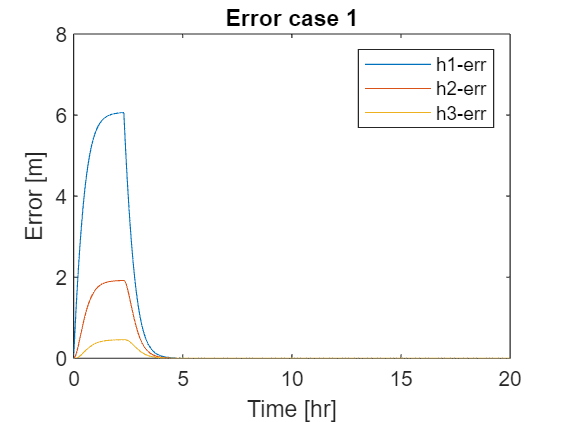

%hold off
plot(out6.e61)
title("Error case 1")
legend('h1-err','h2-err','h3-err')
xlabel('Time [hr]')
ylabel('Error [m]')
ylim([0 8])
hold off

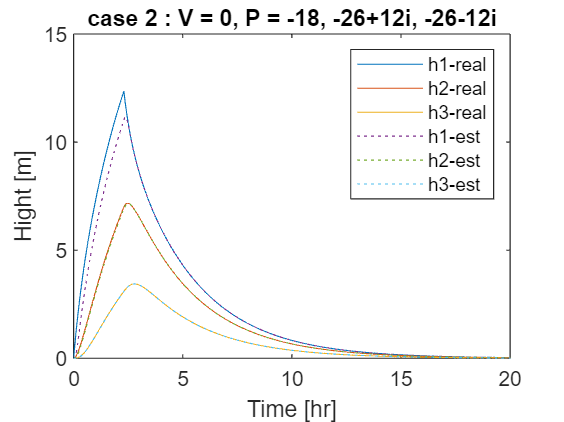


plot(out6.x62)
hold on
plot(out6.xe62,':')
title("case 2 : V = 0, P = "+P6_2(1)+", "+P6_2(2)+", "+P6_2(3))
hold off
legend('h1-real','h2-real','h3-real','h1-est','h2-est','h3-est')
xlabel('Time [hr]')
ylabel('Hight [m]')

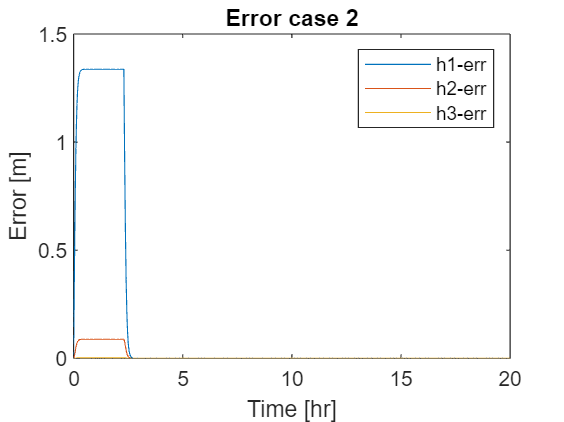


plot(out6.e62)
title("Error case 2")
legend('h1-err','h2-err','h3-err')
xlabel('Time [hr]')
ylabel('Error [m]')
hold off

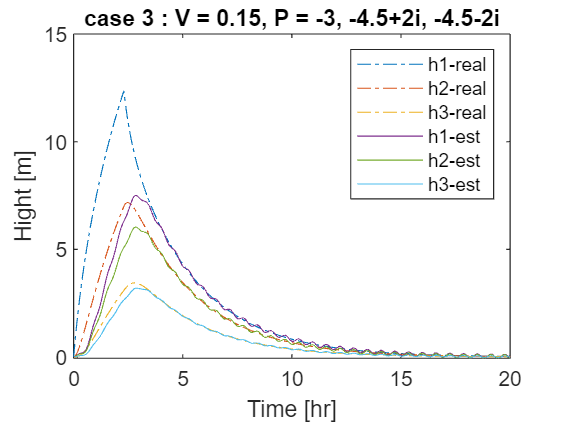


plot(out6.x71,'-.')
hold on
plot(out6.xe71)
title("case 3 : V = 0.15, P = "+P6_1(1)+", "+P6_1(2)+", "+P6_1(3))
hold off
legend('h1-real','h2-real','h3-real','h1-est','h2-est','h3-est')
xlabel('Time [hr]')
ylabel('Hight [m]')

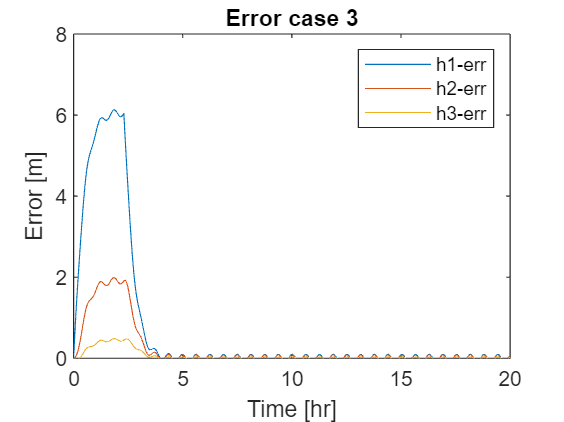


plot(out6.e71)
title("Error case 3")
legend('h1-err','h2-err','h3-err')
xlabel('Time [hr]')
ylabel('Error [m]')
ylim([0 8])
hold off

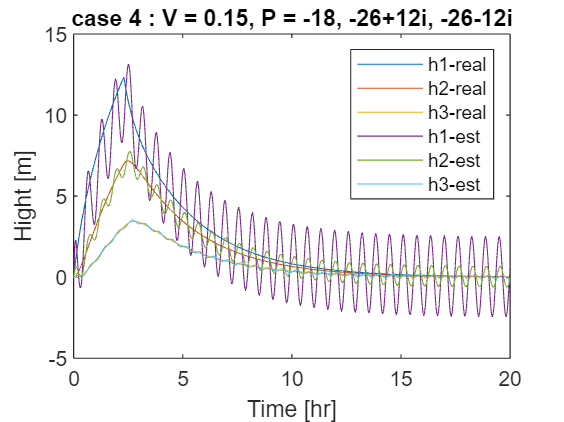


plot(out6.x72)
hold on
plot(out6.xe72)
title("case 4 : V = 0.15, P = "+P6_2(1)+", "+P6_2(2)+", "+P6_2(3))
legend('h1-real','h2-real','h3-real','h1-est','h2-est','h3-est')
xlabel('Time [hr]')
ylabel('Hight [m]')
hold off

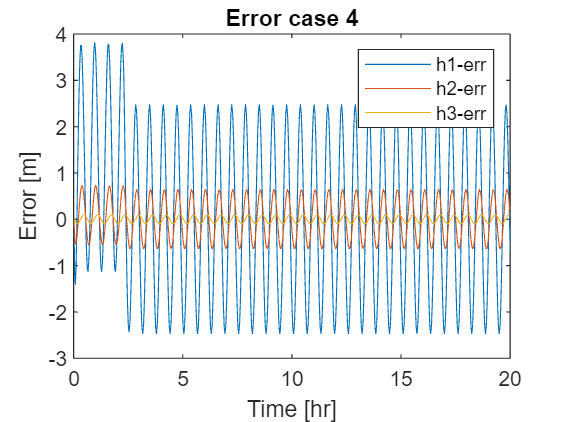

plot(out6.e72)
title("Error case 4")
legend('h1-err','h2-err','h3-err')
xlabel('Time [hr]')
ylabel('Error [m]')
hold off

% part 8

F9 = acker(matA1,matB1u,[Pmin Pmin Pmin]) 

F9 =     3.0029    1.3117    1.6673


K61

K61 =     6.6640    5.8500    2.2000


K61t = K61';
s = tf('s');
matB1d = [1;0;0];
G8 = minreal(matC6 * ((s*eye(3)-matA1)^-1) *matB1u)

G8 =
 
           2.778 s + 4.63
  --------------------------------
  s^3 + 8.333 s^2 + 16.67 s + 4.63
 
Continuous-time transfer function.



G81 = (matC6 * ((s*eye(3)-matA1)^-1) *matB1u);
G8_d = minreal(matC6 * ((s*eye(3)-matA1)^-1) *matB1d)

G8_d =
 
                4.63
  --------------------------------
  s^3 + 8.333 s^2 + 16.67 s + 4.63
 
Continuous-time transfer function.



G8_d1 = (matC6 * ((s*eye(3)-matA1)^-1) *matB1d);
H_s1 = zpk((F9/(s*eye(3)-(matA1-matB1u*F9-K61t*matC6)))*K61t);
L_s1 = zpk(1-(F9/(s*eye(3)-(matA1-matB1u*F9-K61t*matC6)))*matB1u);
H_s = minreal((F9/(s*eye(3)-(matA1-matB1u*F9-(K61')*matC6))*(K61')), 0.0001)

H_s =
 
     31.35 s^2 + 255 s + 450.1
  --------------------------------
  s^3 + 13.31 s^2 + 70.4 s + 72.13
 
Continuous-time transfer function.



L_s = minreal(1 - (F9*(1/(s*eye(3)-(matA1-matB1u*F9-(K61')*matC6))))*(matB1u), 0.0001)

L_s =
 
   s^3 + 12 s^2 + 51.25 s + 72.75
  --------------------------------
  s^3 + 13.31 s^2 + 70.4 s + 72.13
 
Continuous-time transfer function.



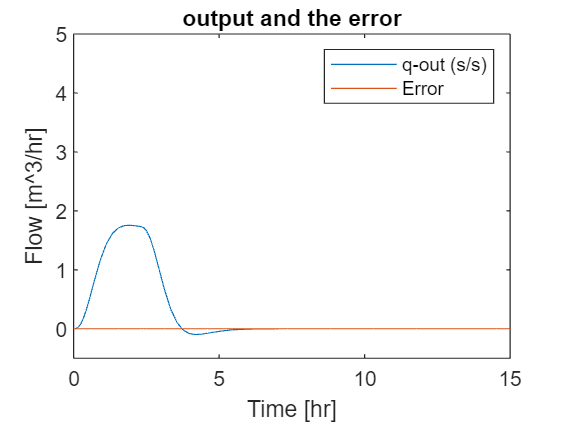


out8 = sim('sim_part8.slx');
plot(out8.y8)
hold on
plot(out8.error8)
title("output and the error")
legend('q-out (s/s)','Error')
ylim([-0.5 5])
xlabel('Time [hr]')
ylabel('Flow [m^3/hr]')

hold off

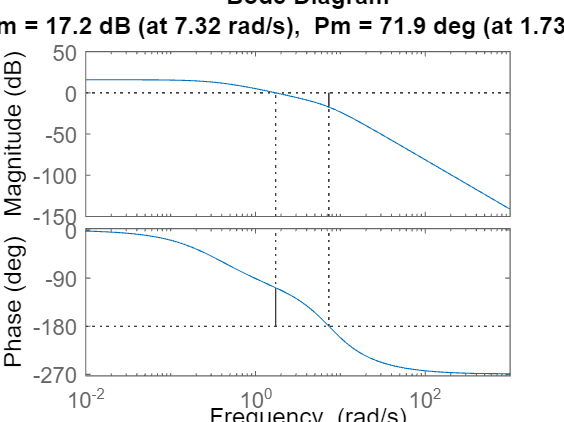

margin(G8*H_s)

[Gain_Margin ,Phase_Margin] = margin(G8*H_s);
Gain_Margin = 20*log10(Gain_Margin)

Gain_Margin = 17.2041

Phase_Margin

Phase_Margin = 71.8915